# ANALYSIS OF LIGHT RESPONSES IN GLIA IN SMH, DATA BY PERCY 2022

 %%Set path to where your codes are
addpath(genpath('X:\Nathalie\data\code'))

## STEP1 LOAD ALL DATA INTO ONE CELL ARRAY------------------------------------------

set the path for the 2p data and the number of cell data

cfg.pathData='X:\Nathalie\other\manuscript\in preparation\DGama_brainphysiology_smh\2p_glia\data\';

load the data into few matrix

[ctrlON,mutON,time]=nj_load2pGliadata_v2(cfg);

calculate the number of dataset

numCTRL=size(ctrlON,1)-1

numCTRL = 8

numMUT=size(mutON,1)-1

numMUT = 12

## SET SOME PARAMETERS FOR THE PLOTS

close all
clear cfg

enter some parameters for the plots into one variable called cfg

cfg.MutID='SMH' %enter the name of your mutant 'ELIPSA', this is for the title

cfg = struct with fields:
    MutID: 'SMH'


cfg.Mutcolor='m' %enter the color you want for your mutantd display, 'm'= magenta, 'c'=cyan

cfg = struct with fields:
       MutID: 'SMH'
    Mutcolor: 'm'


cfg.numCTRL=numCTRL;
cfg.numMUT=numMUT;
cfg.label=["tel" "mid" "hind" "thalamus"];
cfg.brainRegion=char('telencephalon','Midbrain','Hindbrain', 'Thalamus');
cfg

cfg = struct with fields:
          MutID: 'SMH'
       Mutcolor: 'm'
        numCTRL: 8
         numMUT: 12
          label: ["tel"    "mid"    "hind"    "thalamus"]
    brainRegion: [4×13 char]


## PLOT THE AVERAGE RESPONSE FOR ALL CELLS PER FISH

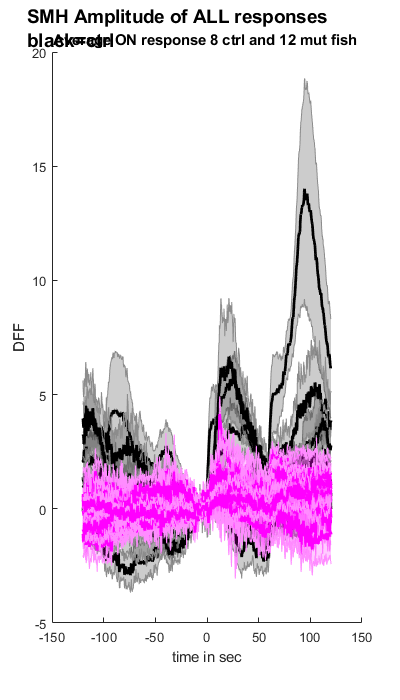

close 
[averageON_ALL]=plot_responseALL_perfish(ctrlON,mutON,time,cfg);

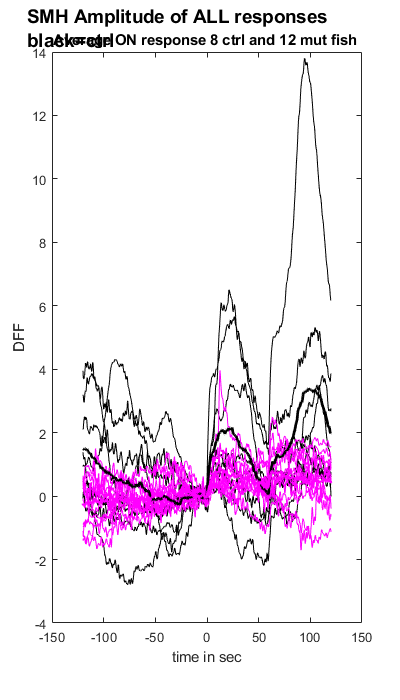

plot_responseALL_perfish2(ctrlON,mutON,time,cfg);

## PLOT THE AVERAGE RESPONSE FOR ALL CELLS FOR ALL FISH

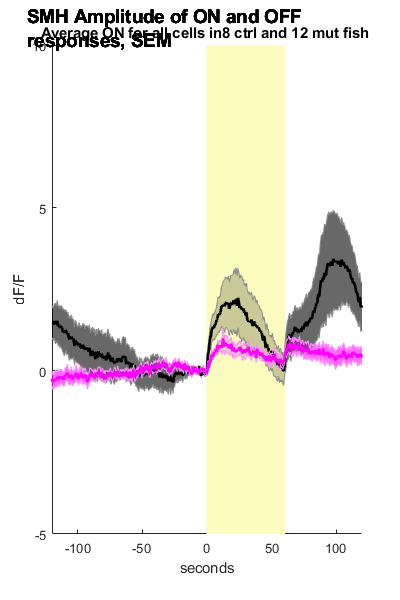

plot_responseALL_average(averageON_ALL,time,cfg);

## PLOT THE AVERAGE RESPONSE FOR ALL CELLS PER FISH

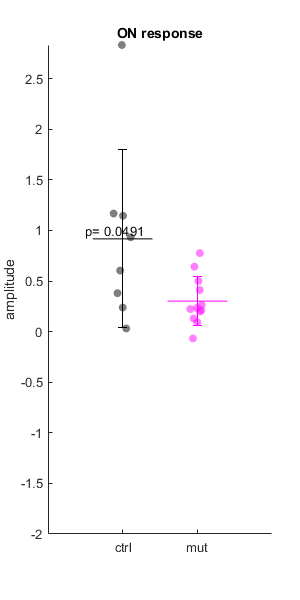

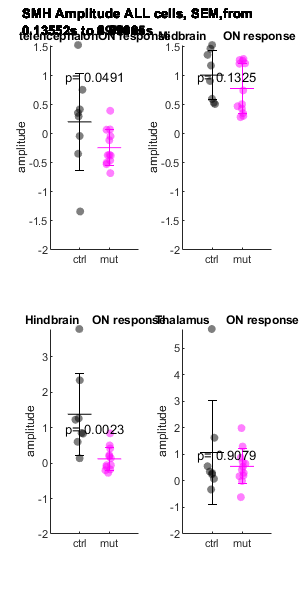

plot_scatterAll(averageON_ALL,ctrlON,mutON, time,cfg)

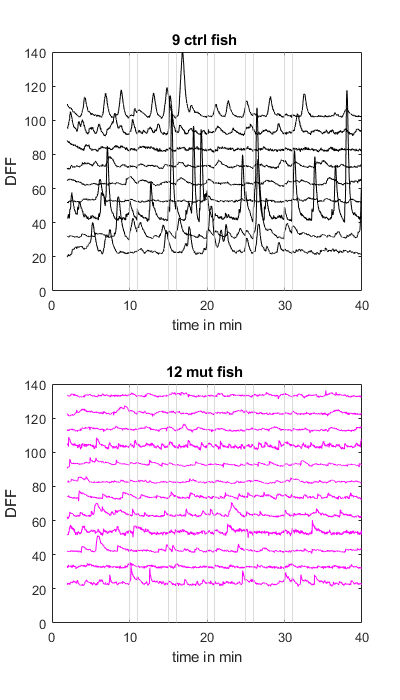

plot_ALL_perfish(ctrlON,mutON,time,cfg)

counter = 1

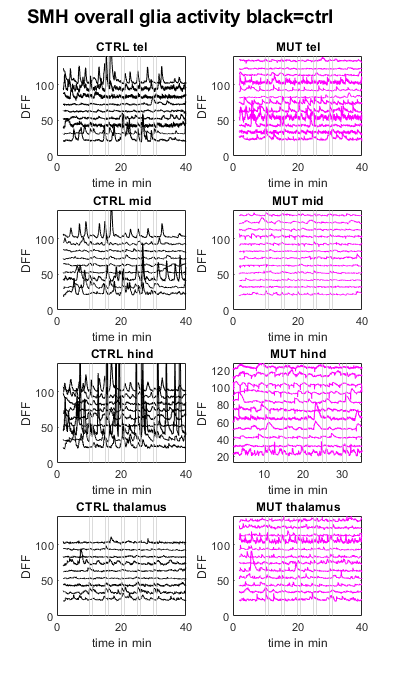

plot_ALL_perfish2(ctrlON,mutON,time,cfg)

## CALCULATE MEAN ACTIVITY

calculate average activity of glia in the dataset

mean and trapz gaves the same difference, just difference y axis

% for i=1:numCTRL
% matCTRL(i)=trapz(mean(ctrlON{1+i, 3},1));
% end
% 
% for i=1:numMUT
% matMUT(i)=trapz(mean(mutON{1+i, 3},1));
% end



for i=1:numCTRL
matCTRL(i)=mean(mean(ctrlON{1+i, 3},1));
end

for i=1:numMUT
matMUT(i)=mean(mean(mutON{1+i, 3},1));
end

ranksum(matCTRL,matMUT)

ans = 0.0360

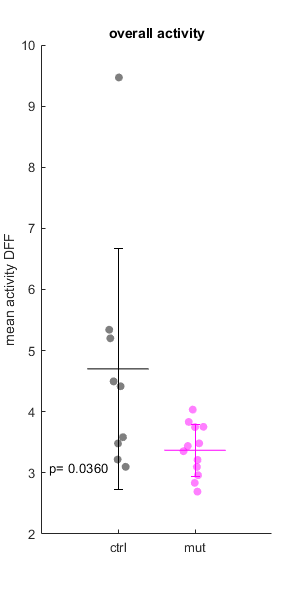


figure (60)
set(gcf,  'Position',[100 100 300 600])
%str= {[cfg.MutID ' Amplitude ALL cells, SEM,from ' num2str(time.stim(onset)) 's to ' num2str(time.stim(offset)) 's']};
% annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',10, 'FontWeight', 'bold', 'LineStyle', 'none');


toplotC=matCTRL;
toplotM=matMUT;
swarmchart(ones(length(toplotC),1), toplotC,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(toplotC,2),1,2),'Color','k')
errorbar(1,mean(toplotC,2), std(toplotC),'Color','k')
swarmchart(2*ones(cfg.numMUT,1), toplotM,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(toplotM,2),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(toplotM,2), std(toplotM),'Color',cfg.Mutcolor)
xlim([0 3]), %ylim([-2 Inf])
ylabel('mean activity DFF')
text(0.1,min(toplotC),['p= '...
     num2str(ranksum(toplotC,toplotM),'%.4f')]);
xticks([1 2])
xticklabels({'ctrl','mut'})
title('overall activity')
%clear toplotC toplotM
hold off

## NESTED FUNCTIONS

function [ctrlON,mutON,time]=nj_load2pGliadata_v2(cfg)

% STEP 1 LOAD THE RESPONDING CELL DATA
path=cfg.pathData;
cd(path)

% STEP1.1 LOAD THE CTRL DATA INTO ONE CELL ARRAY------------------------------------------

stk_files = dir(fullfile(path, '*ctrl*' ));

% makes a cell array called ctrlON for ctrlON datasets and ctrlOFF for ctrlOFF datasets
% raw one is just the title of the columns in the array
ctrlON=cell(1,3);
ctrlON{1,1}='name'; 
ctrlON{1,2}='averageONresponse'; 
ctrlON{1,3}='averageactivity'; 

% I need a counter so that tehre is no empty rows
countON=2;

for i=1:length(stk_files)
load(stk_files(i).name);
fps=amplitude.cfg.originalfps;
    ctrlON{countON,1}=stk_files(i).name;
    ctrlON{countON,2}=amplitude.DFFstim_meanRegion;
    ctrlON{countON,3}=amplitude.DFF_meanRegion;
    countON=countON+1;

time.stim=amplitude.timestim;
time.overall=amplitude.time;
amplitude=[];
end
stk_files=[];


% STEP1.2 LOAD THE MUTANT DATA INTO ONE CELL ARRAY------------------------------------------

stk_files = dir(fullfile(path, '*mut*' ));

% makes a cell array called mutON for mutON datasets and mutOFF for mutOFF datasets
% raw one is just the title of the columns in the array
mutON=cell(1,3);
mutON{1,1}='name'; 
mutON{1,2}='averageONresponse'; 
mutON{1,3}='averageactivity'; 

% I need a counter so that tehre is no empty rows
countON=2;

for i=1:length(stk_files)
load(stk_files(i).name);
fps=amplitude.cfg.originalfps;
    mutON{countON,1}=stk_files(i).name;
    mutON{countON,2}=amplitude.DFFstim_meanRegion;
    mutON{countON,3}=amplitude.DFF_meanRegion;
    countON=countON+1;
amplitude=[];
end

stk_files=[];

end

FUNCTION 1.1 TO PLOT THE AVERAGE DATA FOR ALL CELLS PER ANIMAL FOR ALL ANIMALS ON TOP OF EACH OTHER==========

function plot_responseALL_perfish2(ctrlON,mutON,time,cfg)

figure (31)

set(gcf,  'Position',[100 100 400 700])
str= {[cfg.MutID ' Amplitude of ALL responses black=ctrl']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',14, 'FontWeight', 'bold', 'LineStyle', 'none');

% Average response ON
for i=2:cfg.numCTRL+1  
plot(time.stim,smooth(mean(ctrlON{i,2},1)), 'k'), hold on
xlabel('time in sec')
ylabel('DFF')
averageON_ALL.ctrl(i-1,:)=smooth(mean(ctrlON{i,2},1));
end
for i=2:cfg.numMUT+1
plot(time.stim,smooth(mean(mutON{i,2},1)),'Color', cfg.Mutcolor), hold on
xlabel('time in sec')
ylabel('DFF')
averageON_ALL.mut(i-1,:)=smooth(mean(mutON{i,2},1));
end
plot(time.stim,mean(averageON_ALL.ctrl,1), 'k','LineWidth',2)
plot(time.stim,mean(averageON_ALL.mut,1), 'Color', cfg.Mutcolor,'LineWidth',2)
title(['Average ON response ' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])
hold off
end

function plot_responseALL_perfish3(ctrlON,mutON,time,cfg)

figure (32)
set(gcf,  'Position',[100 100 400 700])
str= {[cfg.MutID ' Amplitude of ALL responses black=ctrl']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',14, 'FontWeight', 'bold', 'LineStyle', 'none');

for k=1:4
% Average response ON
subplot(2,2,k)
for i=2:cfg.numCTRL+1  
plot(time.stim,smooth(ctrlON{i,2}(k,:)), 'k'), hold on
xlabel('time in sec')
ylabel('DFF')
averageON_ALL.ctrl(i-1,:)=smooth(ctrlON{i,2}(k,:));
end
for i=2:cfg.numMUT+1
plot(time.stim,smooth(mutON{i,2}(k,:)),'Color', cfg.Mutcolor), hold on
xlabel('time in sec')
ylabel('DFF')
averageON_ALL.mut(i-1,:)=smooth(mutON{i,2}(k,:));
end
plot(time.stim,mean(averageON_ALL.ctrl,1), 'k','LineWidth',2)
plot(time.stim,mean(averageON_ALL.mut,1), 'Color', cfg.Mutcolor,'LineWidth',2)
title(num2str(cfg.label(k)))
averageON_ALL.ctrl=[];
averageON_ALL.mut=[];
hold off
end
hold off
end


function [averageON_ALL]=plot_responseALL_perfish(ctrlON,mutON,time,cfg)

figure (30)
set(gcf,  'Position',[100 100 400 700])
str= {[cfg.MutID ' Amplitude of ALL responses black=ctrl']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',14, 'FontWeight', 'bold', 'LineStyle', 'none');

% Average response ON
for i=2:cfg.numCTRL+1  
shadedErrorBar(time.stim,mean(ctrlON{i,2},1),std(ctrlON{i,2},[],1)/sqrt(size(ctrlON{i,2},1)),'lineprops', 'k'), hold on
xlabel('time in sec')
ylabel('DFF')
averageON_ALL.ctrl(i-1,:)=mean(ctrlON{i,2},1);
end
for i=2:cfg.numMUT+1
shadedErrorBar(time.stim,mean(mutON{i,2},1),std(mutON{i,2},[],1)/sqrt(size(mutON{i,2},1)),'lineprops', cfg.Mutcolor), hold on
xlabel('time in sec')
ylabel('DFF')
averageON_ALL.mut(i-1,:)=mean(mutON{i,2},1);
end
title(['Average ON response ' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])
hold off

end

function plot_ALL_perfish(ctrlON,mutON,time,cfg)

figure (31)
set(gcf,  'Position',[100 100 400 700])
str= {[cfg.MutID ' Average overall glia activity black=ctrl']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',14, 'FontWeight', 'bold', 'LineStyle', 'none');

% Average response ON
subplot(2,1,1)
for i=2:cfg.numCTRL+1  
plot(time.overall/60,smooth(mean(ctrlON{i,3},1),10)+i*10, 'k'), hold on
xlabel('time in min')
ylabel('DFF')
averageON_ALL.ctrl(i-1,:)=smooth(mean(ctrlON{i,3},1),10);
end
ylim([0 140])
title([num2str(cfg.numCTRL) ' ctrl fish '])
xline([10,11,15,16,20,21,25,26,30,31],'Color', [0.8 0.8 0.8],'LineWidth', 0.5)
hold off
subplot(2,1,2)
for i=2:cfg.numMUT+1
plot(time.overall/60,smooth(mean(mutON{i,3},1),10)+i*10,'Color', cfg.Mutcolor), hold on
xlabel('time in min')
ylabel('DFF')
averageON_ALL.mut(i-1,:)=smooth(mean(mutON{i,3},1),10);
end
ylim([0 140])
title([num2str(cfg.numMUT) ' mut fish '])
xline([10,11,15,16,20,21,25,26,30,31],'Color', [0.8 0.8 0.8],'LineWidth', 0.5)
hold off
end

function plot_ALL_perfish2(ctrlON,mutON,time,cfg)

figure (33)
set(gcf,  'Position',[100 100 400 700])
str= {[cfg.MutID ' overall glia activity black=ctrl']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',14, 'FontWeight', 'bold', 'LineStyle', 'none');

counter=1
for k=1:4
% Average response ON
subplot(4,2,counter)
for i=2:cfg.numCTRL+1  
plot(time.overall/60,smooth(ctrlON{i,3}(k,:),10)+i*10, 'k'), hold on
xlabel('time in min')
ylabel('DFF')
end
ylim([0 140])
title(['CTRL ' num2str(cfg.label(k))])
xline([10,11,15,16,20,21,25,26,30,31],'Color', [0.8 0.8 0.8],'LineWidth', 0.5)
hold off
counter=counter+1;
subplot(4,2,counter)
for i=2:cfg.numMUT+1
plot(time.overall/60,smooth(mutON{i,3}(k,:),10)+i*10,'Color', cfg.Mutcolor), hold on
xlabel('time in min')
ylabel('DFF')
end
ylim([0 140])
title(['MUT ' num2str(cfg.label(k))])
xline([10,11,15,16,20,21,25,26,30,31],'Color', [0.8 0.8 0.8],'LineWidth', 0.5)
hold off
counter=counter+1;
end


end

FUNCTION 1.2 TO PLOT THE AVERAGE DATA FOR ALL RESPONDING CELLS PER ANIMAL FOR ALL ANIMALS ON TOP OF EACH OTHER==========

function [averageONp,averageONi,averageOFFp,averageOFFi] =plot_response_perfish(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg)

figure (30)
set(gcf,  'Position',[100 100 1200 800])
str= {[cfg.MutID ' Amplitude of ON and OFF responses black=ctrl']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',14, 'FontWeight', 'bold', 'LineStyle', 'none');

% Average ONresponding cells activated
subplot(2,2,1), 
for i=2:cfg.numCTRL+1  
shadedErrorBar(time,mean(ctrlON{i,2},1),std(ctrlON{i,2},[],1)/sqrt(size(ctrlON{i,2},1)),'lineprops', 'k'), hold on
xlabel('time in sec')
ylabel('DFF')
averageONp.ctrl(i-1,:)=mean(ctrlON{i,2},1);
end
for i=2:cfg.numMUT+1
shadedErrorBar(time,mean(mutON{i,2},1),std(mutON{i,2},[],1)/sqrt(size(mutON{i,2},1)),'lineprops', cfg.Mutcolor), hold on
xlabel('time in sec')
ylabel('DFF')
averageONp.mut(i-1,:)=mean(mutON{i,2},1);
end
title(['Average ONresponding cells activated for ' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])

% Average ONresponding cells inhibited
subplot(2,2,2), 
for i=2:cfg.numCTRL+1  
shadedErrorBar(time,mean(ctrlON{i,3},1),std(ctrlON{i,2},[],1)/sqrt(size(ctrlON{i,3},1)),'lineprops', 'k'), hold on
xlabel('time in sec')
ylabel('DFF')
averageONi.ctrl(i-1,:)=mean(ctrlON{i,3},1);
end
for i=2:cfg.numMUT+1 
shadedErrorBar(time,mean(mutON{i,3},1),std(mutON{i,2},[],1)/sqrt(size(mutON{i,3},1)),'lineprops', cfg.Mutcolor), hold on
xlabel('time in sec')
ylabel('DFF')
averageONi.mut(i-1,:)=mean(mutON{i,3},1);
end
title(['Average ONresponding cells inhibited for ' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])

% Average OFFresponding cells activated
subplot(2,2,3), 
for i=2:cfg.numCTRL+1  
shadedErrorBar(time,mean(ctrlOFF{i,2},1),std(ctrlOFF{i,2},[],1)/sqrt(size(ctrlOFF{i,2},1)),'lineprops', 'k'), hold on
xlabel('time in sec')
ylabel('DFF')
averageOFFp.ctrl(i-1,:)=mean(ctrlOFF{i,2},1);
end
for i=2:cfg.numMUT+1
shadedErrorBar(time,mean(mutOFF{i,2},1),std(mutOFF{i,2},[],1)/sqrt(size(mutOFF{i,2},1)),'lineprops', cfg.Mutcolor), hold on
xlabel('time in sec')
ylabel('DFF')
averageOFFp.mut(i-1,:)=mean(mutOFF{i,2},1);
end
title(['Average OFFresponding cells activated for ' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])

% Average OFFresponding cells
subplot(2,2,4), 
for i=2:cfg.numCTRL+1 
shadedErrorBar(time,mean(ctrlOFF{i,3},1),std(ctrlOFF{i,3},[],1)/sqrt(size(ctrlOFF{i,3},1)),'lineprops', 'k'), hold on
xlabel('time in sec')
ylabel('DFF')
averageOFFi.ctrl(i-1,:)=mean(ctrlOFF{i,3},1);
end
for i=2:cfg.numMUT+1
shadedErrorBar(time,mean(mutOFF{i,3},1),std(mutOFF{i,3},[],1)/sqrt(size(mutOFF{i,3},1)),'lineprops', cfg.Mutcolor), hold on
xlabel('time in sec')
ylabel('DFF')
averageOFFi.mut(i-1,:)=mean(mutOFF{i,3},1);
end
title(['Average OFFresponding cells inhibited for ' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])
hold off
end



% FUNCTION2.1 PLOT THE AVERAGE OF THE AVERAGE OF RESPONDING CELLS FOR ALL ANIMALS ON TOP OF EACH OTHER================== 

function plot_response_average(averageONp,averageONi,averageOFFp,averageOFFi,time,cfg)

figure (40)
set(gcf,  'Position',[100 100 1200 800])
str= {[cfg.MutID ' Amplitude of ON and OFF responses, SEM']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',14, 'FontWeight', 'bold', 'LineStyle', 'none');

subplot(2,2,1)
rectangle('Position',[0 -8 60 70],'FaceColor',[0.99 0.99 0.75], 'EdgeColor',[0.99 0.99 0.75]), hold on
shadedErrorBar(time,mean(averageONp.ctrl,1),std(averageONp.ctrl,[],1)/sqrt(size(averageONp.ctrl,1)),'lineprops', 'k')
shadedErrorBar(time,mean(averageONp.mut,1),std(averageONp.mut,[],1)/sqrt(size(averageONp.mut,1)),'lineprops', cfg.Mutcolor)
title(['Average ON activated for ' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])
xlim([-120 120])
ylim([-5 60])
xlabel('seconds')
ylabel('dF/F')

subplot(2,2,2)
rectangle('Position',[0 -40 60 80],'FaceColor',[0.99 0.99 0.75], 'EdgeColor',[0.99 0.99 0.75]), hold on
shadedErrorBar(time,mean(averageONi.ctrl,1),std(averageONi.ctrl,[],1)/sqrt(size(averageONi.ctrl,1)),'lineprops', 'k')
shadedErrorBar(time,mean(averageONi.mut,1),std(averageONi.mut,[],1)/sqrt(size(averageONi.mut,1)),'lineprops', cfg.Mutcolor)
title(['Average ON inhibited for ' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])
xlim([-120 120])
ylim([-35 40])
xlabel('seconds')
ylabel('dF/F')

subplot(2,2,3)
rectangle('Position',[-60 -8 60 70],'FaceColor',[0.99 0.99 0.75], 'EdgeColor',[0.99 0.99 0.75]), hold on
shadedErrorBar(time,mean(averageOFFp.ctrl,1),std(averageOFFp.ctrl,[],1)/sqrt(size(averageOFFp.ctrl,1)),'lineprops', 'k')
shadedErrorBar(time,mean(averageOFFp.mut,1),std(averageOFFp.mut,[],1)/sqrt(size(averageOFFp.mut,1)),'lineprops', cfg.Mutcolor)
title(['Average OFF activated for ' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])
xlim([-120 120])
ylim([-5 60])
xlabel('seconds')
ylabel('dF/F')

subplot(2,2,4)
rectangle('Position',[-60 -40 60 70],'FaceColor',[0.99 0.99 0.75], 'EdgeColor',[0.99 0.99 0.75]), hold on
shadedErrorBar(time,mean(averageOFFi.ctrl,1),std(averageOFFi.ctrl,[],1)/sqrt(size(averageOFFi.ctrl,1)),'lineprops', 'k')
shadedErrorBar(time,mean(averageOFFi.mut,1),std(averageOFFi.mut,[],1)/sqrt(size(averageOFFi.mut,1)),'lineprops', cfg.Mutcolor)
title(['Average OFF inhibited for ' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])
xlim([-120 120])
ylim([-35 30])
xlabel('seconds')
ylabel('dF/F')
hold off
end


% FUNCTION2.2 PLOT THE AVERAGE OF THE AVERAGE OF ALL CELLS FOR ALL ANIMALS ON TOP OF EACH OTHER==================

function plot_responseALL_average(averageON_ALL,time,cfg)


figure (40)
set(gcf,  'Position',[100 100 400 600])
str= {[cfg.MutID ' Amplitude of ON and OFF responses, SEM']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',14, 'FontWeight', 'bold', 'LineStyle', 'none');


rectangle('Position',[0 -8 60 70],'FaceColor',[0.99 0.99 0.75], 'EdgeColor',[0.99 0.99 0.75]), hold on
shadedErrorBar(time.stim,mean(averageON_ALL.ctrl,1),std(averageON_ALL.ctrl,[],1)/sqrt(size(averageON_ALL.ctrl,1)),'lineprops', 'k')
shadedErrorBar(time.stim,mean(averageON_ALL.mut,1),std(averageON_ALL.mut,[],1)/sqrt(size(averageON_ALL.mut,1)),'lineprops', cfg.Mutcolor)
title(['Average ON for all cells in' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])
xlim([-120 120])
ylim([-5 10])
xlabel('seconds')
ylabel('dF/F')
hold off

end

FUNCTION3.1 PLOT AVERAGE AMPLITUDE FOR 10SEC AFTER FOR RESPONDING CELLS

function plot_scatter(averageONp,averageONi,averageOFFp,averageOFFi,time,cfg)

% enter the frames. this is for 10sec
onset=470%465;
offset=493%503;

figure (50)
set(gcf,  'Position',[100 100 400 600])
str= {[cfg.MutID ' Amplitude, SEM,from ' num2str(time(onset)) 's to ' num2str(time(offset)) 's']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',10, 'FontWeight', 'bold', 'LineStyle', 'none');

subplot(2,2,1)
toplotC=averageONp.ctrl(:,onset:offset);
toplotM=averageONp.mut(:,onset:offset);
swarmchart(ones(cfg.numCTRL,1), mean(toplotC,2),'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(mean(toplotC,2)),1,2),'Color','k')
errorbar(1,mean(mean(toplotC,2)), std(mean(toplotC,2)),'Color','k')
swarmchart(2*ones(cfg.numMUT,1), mean(toplotM,2),cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(mean(toplotM,2)),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(mean(toplotM,2)), std(mean(toplotM,2)),'Color',cfg.Mutcolor)
xlim([0 3]), ylim([0 Inf])
ylabel('amplitude')
text(0.5,10,['p= '...
    num2str(ranksum(mean(toplotC,2),mean(toplotM,2)),'%.3f')]);
xticks([1 2])
xticklabels({'ctrl','mut'})
title('ON activated')
clear toplotC toplotM

subplot(2,2,2)
toplotC=averageONi.ctrl(:,onset:offset);
toplotM=averageONi.mut(:,onset:offset);
swarmchart(ones(cfg.numCTRL,1), mean(toplotC,2),'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(mean(toplotC,2)),1,2),'Color','k')
errorbar(1,mean(mean(toplotC,2)), std(mean(toplotC,2)),'Color','k')
swarmchart(2*ones(cfg.numMUT,1), mean(toplotM,2),cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(mean(toplotM,2)),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(mean(toplotM,2)), std(mean(toplotM,2)),'Color',cfg.Mutcolor)
xlim([0 3]), ylim([-Inf 0])
ylabel('amplitude')
text(0.5,-10,['p= '...
    num2str(ranksum(mean(toplotC,2),mean(toplotM,2)),'%.3f')]);
xticks([1 2])
xticklabels({'ctrl','mut'})
title('ON inhibited')
clear toplotC toplotM


subplot(2,2,3)
toplotC=averageOFFp.ctrl(:,onset:offset);
toplotM=averageOFFp.mut(:,onset:offset);
swarmchart(ones(cfg.numCTRL,1), mean(toplotC,2),'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(mean(toplotC,2)),1,2),'Color','k')
errorbar(1,mean(mean(toplotC,2)), std(mean(toplotC,2)),'Color','k')
swarmchart(2*ones(cfg.numMUT,1), mean(toplotM,2),cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(mean(toplotM,2)),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(mean(toplotM,2)), std(mean(toplotM,2)),'Color',cfg.Mutcolor)
xlim([-1 3]), ylim([0 Inf])
ylabel('amplitude')
text(0.5,10,['p= '...
    num2str(ranksum(mean(toplotC,2),mean(toplotM,2)),'%.3f')]);
xticks([1 2])
xticklabels({'ctrl','mut'})
title('OFF activated')
clear toplotC toplotM

subplot(2,2,4)
toplotC=averageOFFi.ctrl(:,onset:offset);
toplotM=averageOFFi.mut(:,onset:offset);
swarmchart(ones(cfg.numCTRL,1), mean(toplotC,2),'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(mean(toplotC,2)),1,2),'Color','k')
errorbar(1,mean(mean(toplotC,2)), std(mean(toplotC,2)),'Color','k')
swarmchart(2*ones(cfg.numMUT,1), mean(toplotM,2),cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(mean(toplotM,2)),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(mean(toplotM,2)), std(mean(toplotM,2)),'Color',cfg.Mutcolor)
xlim([-1 3]), ylim([-Inf 0])
ylabel('amplitude')
text(0.5,-10,['p= '...
    num2str(ranksum(mean(toplotC,2),mean(toplotM,2)),'%.3f')]);
xticks([1 2])
xticklabels({'ctrl','mut'})
title('OFF inhibited')
clear toplotC toplotM
hold off
end


FUNCTION3.2 PLOT AVERAGE AMPLITUDE FOR 10SEC AFTER FOR RESPONDING CELLS

function plot_scatterAll(averageON_ALL,ctrlON,mutON, time,cfg)

% enter the frames. 
onset=465;%this is time 0
offset=483;%this is for 5 sec
%offset=503;% this is for 10sec
%offset=541; %this is 20 sec
%offset=580;% this is for 30sec

figure (51)
set(gcf,  'Position',[100 100 300 600])
str= {[cfg.MutID ' Amplitude ALL cells, SEM,from ' num2str(time.stim(onset)) 's to ' num2str(time.stim(offset)) 's']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',10, 'FontWeight', 'bold', 'LineStyle', 'none');


toplotC=averageON_ALL.ctrl(:,onset:offset);
toplotM=averageON_ALL.mut(:,onset:offset);
swarmchart(ones(cfg.numCTRL,1), mean(toplotC,2),'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(mean(toplotC,2)),1,2),'Color','k')
errorbar(1,mean(mean(toplotC,2)), std(mean(toplotC,2)),'Color','k')
swarmchart(2*ones(cfg.numMUT,1), mean(toplotM,2),cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(mean(toplotM,2)),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(mean(toplotM,2)), std(mean(toplotM,2)),'Color',cfg.Mutcolor)
xlim([0 3]), ylim([-2 Inf])
ylabel('amplitude')
text(0.5,1,['p= '...
    num2str(ranksum(mean(toplotC,2),mean(toplotM,2)),'%.4f')]);
xticks([1 2])
xticklabels({'ctrl','mut'})
title('ON response')
clear toplotC toplotM
hold off



figure (52)
for k=1:4
set(gcf,  'Position',[100 100 300 600])
str= {[cfg.MutID ' Amplitude ALL cells, SEM,from ' num2str(time.stim(onset)) 's to ' num2str(time.stim(offset)) 's']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',10, 'FontWeight', 'bold', 'LineStyle', 'none');

subplot(2,2,k)
for i=1:cfg.numCTRL 
matrixC(i,:)=mean(ctrlON{i+1,2}(k,:),1);
end
for i=1:cfg.numMUT 
matrixM(i,:)=mean(mutON{i+1,2}(k,:),1);
end
toplotC=matrixC(:,onset:offset);
toplotM=matrixM(:,onset:offset);
swarmchart(ones(cfg.numCTRL,1), mean(toplotC,2),'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(mean(toplotC,2)),1,2),'Color','k')
errorbar(1,mean(mean(toplotC,2)), std(mean(toplotC,2)),'Color','k')
swarmchart(2*ones(cfg.numMUT,1), mean(toplotM,2),cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(mean(toplotM,2)),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(mean(toplotM,2)), std(mean(toplotM,2)),'Color',cfg.Mutcolor)
xlim([0 3]), ylim([-2 Inf])
ylabel('amplitude')
text(0.5,1,['p= '...
    num2str(ranksum(mean(toplotC,2),mean(toplotM,2)),'%.4f')]);
xticks([1 2])
xticklabels({'ctrl','mut'})
title([cfg.brainRegion(k,:) 'ON response'])
clear toplotC toplotM matrixC matrixM
hold off
end
hold off

end


FUNCTION3.3 PLOT CUMULATIVE HISTOGRAM FOR 10SEC AFTER STIMULUS FOR ALL CELLS

function [Nctrl,Nmut]=nj_plotCellResponseLight(ctrl,mut,cfg)

% written by Nathalie Jurisch-Yaksi February 2022
% this code does

% FIGURES: PLOT the % of time a cell is above a threshold of x*percentile============

close all
clear Nctrl Nmut edges

%% below will plot the data for each fish (i) and the entire brain
% plot ctrl fish
for i=1:cfg.numCTRL
figure (1),
xline(0,'k--')
matrix=ctrl{i+1, 6};
[Nctrl(i,:),edges(i,:)]=histcounts(mean(matrix(:,cfg.onset:cfg.offset),2), [-50:cfg.binSize:500],'Normalization', cfg.type); 
plot(edges(i,1:end-1)+cfg.binSize/2, 100*(Nctrl(i,:)),'k','LineWidth',0.5), hold on
clear  matrix
end
% plot mut fish
for i=1:cfg.numMUT
figure (1),
matrix=mut{i+1, 6};
[Nmut(i,:),edges(i,:)]=histcounts(mean(matrix(:,cfg.onset:cfg.offset),2), [-50:cfg.binSize:500],'Normalization', cfg.type); 
plot(edges(i,1:end-1)+cfg.binSize/2, 100*(Nmut(i,:)),cfg.Mutcolor,'LineWidth',0.5), hold on
clear  matrix
end
% plot the average of ctrl and mut on top in bold
figure (1), 
plot(edges(i,1:end-1)+cfg.binSize/2, 100*(mean(Nctrl,1)),'k','LineWidth',3), hold on
plot(edges(i,1:end-1)+cfg.binSize/2, 100*(mean(Nmut,1)),cfg.Mutcolor,'LineWidth',3), hold on
title (['allbrain, condition ' cfg.title])
xlabel('DFF [%]')
ylabel('% cells')
xlim([-20 150])
ylim([0 100])

% plot a shadded Error Bar with the average/SEM of ctrl and mut 
figure (10), 
xline(0,'k--')
shadedErrorBar(edges(1,1:end-1)+cfg.binSize/2, 100*(mean(Nctrl,1)), 100*(std((Nctrl),[],1)/sqrt(size(Nctrl,1))),'lineprops', 'k'), hold on
shadedErrorBar(edges(1,1:end-1)+cfg.binSize/2, 100*(mean(Nmut,1)), 100*(std((Nmut),[],1)/sqrt(size(Nmut,1))),'lineprops', cfg.Mutcolor), 
title (['allbrain, condition ' cfg.title])
ylabel('% cells')
xlabel('DFF [%]')
xlim([-20 150])
ylim([0 100])

[h,p] = kstest2(mean(Nctrl,1),mean(Nmut,1));
text(5,50,['kstest, p=' num2str(p)])
clear Nctrl Nmut

%%
for k=1:4;
% plot ctrl fish
for i=1:cfg.numCTRL
figure (2),
subplot(2,2,k),
xline(0,'k--')
matrix=ctrl{i+1, 6}(ctrl{i+1,7}(:,4)==k,:);
[Nctrl(i,:),edges(i,:)]=histcounts(mean(matrix(:,cfg.onset:cfg.offset),2), [-50:cfg.binSize:500],'Normalization', cfg.type); 
plot(edges(i,1:end-1)+cfg.binSize/2, 100*(Nctrl(i,:)),'k','LineWidth',0.5), hold on
clear matrix
end

% plot mut fish
for i=1:cfg.numMUT
figure (2),
subplot(2,2,k),
matrix=mut{i+1, 6}(mut{i+1,7}(:,4)==k,:);
[Nmut(i,:),edges(i,:)]=histcounts(mean(matrix(:,cfg.onset:cfg.offset),2), [-50:cfg.binSize:500],'Normalization', cfg.type); 
plot(edges(i,1:end-1)+cfg.binSize/2, 100*(Nmut(i,:)),cfg.Mutcolor,'LineWidth',0.5), hold on
clear  matrix
end
% plot the average of ctrl and mut on top in bold
figure (2), 
subplot(2,2,k),
plot(edges(i,1:end-1)+cfg.binSize/2, 100*mean(Nctrl,1),'k','LineWidth',3), hold on
plot(edges(i,1:end-1)+cfg.binSize/2, 100*mean(Nmut,1),cfg.Mutcolor,'LineWidth',3), hold on
title ([cfg.brainRegion(k,:) ' upon ' cfg.title])
xlabel('DFF [%]')
ylabel('% cells')
xlim([-20 150])
ylim([0 100])

% plot a shadded Error Bar with the average/SEM of ctrl and mut 
figure (11), 
subplot(2,2,k),
xline(0,'k--')
shadedErrorBar(edges(1,1:end-1)+cfg.binSize/2, 100*(mean(Nctrl,1)), 100*(std((Nctrl),[],1)/sqrt(size(Nctrl,1))),'lineprops', 'k'), hold on
shadedErrorBar(edges(1,1:end-1)+cfg.binSize/2, 100*(mean(Nmut,1)), 100*(std((Nmut),[],1)/sqrt(size(Nmut,1))),'lineprops', cfg.Mutcolor), 
title ([cfg.brainRegion(k,:) ' upon ' cfg.title ', SEM'])
%xlabel(['% time above ' num2str(threshold) '*' num2str(percentile) 'th percentile'])
xlabel('DFF [%]')
ylabel('% cells')
xlim([-20 150])
ylim([0 100])
[h,p] = kstest2(mean(Nctrl,1),mean(Nmut,1));
text(5,50,['kstest, p=' num2str(p)])
%clear Nmut Nctrl
end
end


FUNCTION4 calculate percentage of activated and inhibited cells

function calculatepercentage(ctrlON,ctrlOFF,mutON,mutOFF,cfg)

for i=2: size(ctrlON,1)
    ctrlON{i,9}=size(ctrlON{i, 2},1)/size(ctrlON{i, 6},1);
    ctrlON{i,10}=size(ctrlON{i, 3},1)/size(ctrlON{i, 6},1);
end
for i=2: size(ctrlOFF,1)
    ctrlOFF{i,9}=size(ctrlOFF{i, 2},1)/size(ctrlOFF{i, 6},1);
    ctrlOFF{i,10}=size(ctrlOFF{i, 3},1)/size(ctrlOFF{i, 6},1);
end

for i=2: size(mutON,1)
    mutON{i,9}=size(mutON{i, 2},1)/size(mutON{i, 6},1);
    mutON{i,10}=size(mutON{i, 3},1)/size(mutON{i, 6},1);
end
for i=2: size(mutOFF,1)
    mutOFF{i,9}=size(mutOFF{i, 2},1)/size(mutOFF{i, 6},1);
    mutOFF{i,10}=size(mutOFF{i, 3},1)/size(mutOFF{i, 6},1);
end
figure (60), 
set(gcf,  'Position',[100 100 400 600])
str= {[cfg.MutID ' %responding cells']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',10, 'FontWeight', 'bold', 'LineStyle', 'none');

subplot(2,2,1)
toplotC=100*cell2mat(ctrlON(2:end, 9));
toplotM=100*cell2mat(mutON(2:end, 9));
swarmchart(ones(size(ctrlON,1)-1,1), toplotC,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(toplotC),1,2),'Color','k')
errorbar(1,mean(toplotC), std(toplotC),'Color','k')
swarmchart(2*ones(size(mutON,1)-1,1), toplotM,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(toplotM),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(toplotM), std(toplotM),'Color',cfg.Mutcolor)
xlim([0 3]),ylim([0 Inf])
ylabel('% responding cells')
text(0.5,5,['p= '...
    num2str(ranksum(toplotC,toplotM),'%.3f')])
xticks([1 2])
xticklabels({'ctrl','mut'})
title('ON activated')
clear toplotC toplotM

subplot(2,2,2)
toplotC=100*cell2mat(ctrlON(2:end, 10));
toplotM=100*cell2mat(mutON(2:end, 10));
swarmchart(ones(size(ctrlON,1)-1,1), toplotC,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(toplotC),1,2),'Color','k')
errorbar(1,mean(toplotC), std(toplotC),'Color','k')
swarmchart(2*ones(size(mutON,1)-1,1), toplotM,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(toplotM),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(toplotM), std(toplotM),'Color',cfg.Mutcolor)
xlim([0 3]),ylim([0 Inf])
ylabel('% responding cells')
text(0.5,1,['p= '...
    num2str(ranksum(toplotC,toplotM),'%.3f')])
xticks([1 2])
xticklabels({'ctrl','mut'})
title(' ON inhibited')
clear toplotC toplotM

subplot(2,2,3)
toplotC=100*cell2mat(ctrlOFF(2:end, 9));
toplotM=100*cell2mat(mutOFF(2:end, 9));
swarmchart(ones(size(ctrlON,1)-1,1), toplotC,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(toplotC),1,2),'Color','k')
errorbar(1,mean(toplotC), std(toplotC),'Color','k')
swarmchart(2*ones(size(mutON,1)-1,1), toplotM,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(toplotM),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(toplotM), std(toplotM),'Color',cfg.Mutcolor)
xlim([0 3]),ylim([0 Inf])
ylabel('% responding cells')
text(0.5,5,['p= '...
    num2str(ranksum(toplotC,toplotM),'%.3f')])
xticks([1 2])
xticklabels({'ctrl','mut'})
title('OFF activated')
clear toplotC toplotM

subplot(2,2,4)
toplotC=100*cell2mat(ctrlOFF(2:end, 10));
toplotM=100*cell2mat(mutOFF(2:end, 10));
swarmchart(ones(size(ctrlON,1)-1,1), toplotC,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(toplotC),1,2),'Color','k')
errorbar(1,mean(toplotC), std(toplotC),'Color','k')
swarmchart(2*ones(size(mutON,1)-1,1), toplotM,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(toplotM),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(toplotM), std(toplotM),'Color',cfg.Mutcolor)
xlim([0 3]),ylim([0 Inf])
ylabel('% responding cells')
text(0.5,1,['p= '...
    num2str(ranksum(toplotC,toplotM),'%.3f')])
xticks([1 2])
xticklabels({'ctrl','mut'})
title('OFF activated')
clear toplotC toplotM
end


FUNCTION 5 plots % response per brain region

function plot_response_perregion(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg)

close all
%% calculate number of responding cells per region
NumCtrl=[];
NumMut=[];
jj=[1,4,2,3]; %reorder so that Hb is between Tel and OT, added 14.03.2023

% calculate responding cells per brain region
for k=1:cfg.numCTRL
for ik=1:4; %there are four brain region
    j=jj(ik);
NumCtrl.ON.activated(k,ik)=length(find(ctrlON{k+1, 4}(:,4)==j))/sum(ctrlON{k+1, 7}(:,4)==j)*100;  
NumCtrl.OFF.activated(k,ik)=length(find(ctrlOFF{k+1, 4}(:,4)==j))/sum(ctrlOFF{k+1, 7}(:,4)==j)*100;
NumCtrl.ON.inhibited(k,ik)=length(find(ctrlON{k+1, 5}(:,4)==j))/sum(ctrlON{k+1, 7}(:,4)==j)*100;
NumCtrl.OFF.inhibited(k,ik)=length(find(ctrlOFF{k+1, 5}(:,4)==j))/sum(ctrlOFF{k+1, 7}(:,4)==j)*100;

end
end

for k=1:cfg.numMUT
for ik=1:4; %there are four brain region
    j=jj(ik);
NumMut.ON.activated(k,ik)=length(find(mutON{k+1, 4}(:,4)==j))/sum(mutON{k+1, 7}(:,4)==j)*100;  
NumMut.OFF.activated(k,ik)=length(find(mutOFF{k+1, 4}(:,4)==j))/sum(mutOFF{k+1, 7}(:,4)==j)*100;  
NumMut.ON.inhibited(k,ik)=length(find(mutON{k+1, 5}(:,4)==j))/sum(mutON{k+1, 7}(:,4)==j)*100;  
NumMut.OFF.inhibited(k,ik)=length(find(mutOFF{k+1, 5}(:,4)==j))/sum(mutOFF{k+1, 7}(:,4)==j)*100;
end
end

figure (70),
set(gcf,  'Position',[100 100 800 600])
str= {[cfg.MutID ' % responding cells per brain area black=ctrl']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',14, 'FontWeight', 'bold', 'LineStyle', 'none');

subplot(2,2,1)
toplotC=NumCtrl.ON.activated;
toplotM=NumMut.ON.activated;
swarmchart(repmat([1 2 3 4], cfg.numCTRL,1), toplotC,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii,mean(toplotC(:,ii)), std(toplotC(:,ii)),'Color','k', 'Marker','_')
end
swarmchart(repmat([1.5 2.5 3.5 4.5], cfg.numMUT,1), toplotM,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii+0.5,mean(toplotM(:,ii)), std(toplotM(:,ii)),'Color',cfg.Mutcolor, 'Marker','_')
end
xlim([-10 5]), ylim([0 80])
ylabel('% of responding cells')
for i=1:4
p(i)=ranksum(toplotC(:,i),toplotM(:,i));
end
text(0,-5,num2str(['Tel:' sprintf('%.3f',p(1))...
    ' Hb:' sprintf('%.3f',p(2)) ' OT:' sprintf('%.3f',p(3))...
    ' Hind:' sprintf('%.3f',p(4))]))
xticks([1.25 2.25 3.25 4.25])
xticklabels({'Tel', 'Hab','OT', 'Hind'})
title('ON activated')
clear toplotC toplotM p
hold off

subplot(2,2,2)
toplotC=NumCtrl.ON.inhibited;
toplotM=NumMut.ON.inhibited;
swarmchart(repmat([1 2 3 4], cfg.numCTRL,1), toplotC,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii,mean(toplotC(:,ii)), std(toplotC(:,ii)),'Color','k', 'Marker','_')
end
swarmchart(repmat([1.5 2.5 3.5 4.5], cfg.numMUT,1), toplotM,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii+0.5,mean(toplotM(:,ii)), std(toplotM(:,ii)),'Color',cfg.Mutcolor, 'Marker','_')
end
xlim([-10 5]), ylim([-1 10])
ylabel('% of responding cells')

for i=1:4
p(i)=ranksum(toplotC(:,i),toplotM(:,i));
end
text(0,-5,num2str(['Tel:' sprintf('%.3f',p(1))...
    ' Hb:' sprintf('%.3f',p(2)) ' OT:' sprintf('%.3f',p(3))...
    ' Hind:' sprintf('%.3f',p(4))]))
xticks([1.25 2.25 3.25 4.25])
xticklabels({'Tel', 'Hab','OT', 'Hind'})
title('ON inhibited')
clear toplotC toplotM p
hold off


subplot(2,2,3)
toplotC=NumCtrl.OFF.activated;
toplotM=NumMut.OFF.activated;
swarmchart(repmat([1 2 3 4], cfg.numCTRL,1), toplotC,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii,mean(toplotC(:,ii)), std(toplotC(:,ii)),'Color','k', 'Marker','_')
end
swarmchart(repmat([1.5 2.5 3.5 4.5], cfg.numMUT,1), toplotM,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii+0.5,mean(toplotM(:,ii)), std(toplotM(:,ii)),'Color',cfg.Mutcolor, 'Marker','_')
end
xlim([-10 5]), ylim([0 80])
ylabel('% of responding cells')
for i=1:4
p(i)=ranksum(toplotC(:,i),toplotM(:,i));
end
text(0,-5,num2str(['Tel:' sprintf('%.3f',p(1))...
    ' Hb:' sprintf('%.3f',p(2)) ' OT:' sprintf('%.3f',p(3))...
    ' Hind:' sprintf('%.3f',p(4))]))
xticks([1.25 2.25 3.25 4.25])
xticklabels({'Tel', 'Hab','OT', 'Hind'})
title('OFF activated')
clear toplotC toplotM p
hold off


subplot(2,2,4)
toplotC=NumCtrl.OFF.inhibited;
toplotM=NumMut.OFF.inhibited;
swarmchart(repmat([1 2 3 4], cfg.numCTRL,1), toplotC,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii,mean(toplotC(:,ii)), std(toplotC(:,ii)),'Color','k', 'Marker','_')
end
swarmchart(repmat([1.5 2.5 3.5 4.5], cfg.numMUT,1), toplotM,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii+0.5,mean(toplotM(:,ii)), std(toplotM(:,ii)),'Color',cfg.Mutcolor, 'Marker','_')
end
xlim([-10 5]), ylim([-1 25])
ylabel('% of responding cells')
for i=1:4
p(i)=ranksum(toplotC(:,i),toplotM(:,i));
end
text(0,-5,num2str(['Tel:' sprintf('%.3f',p(1))...
    ' Hb:' sprintf('%.3f',p(2)) ' OT:' sprintf('%.3f',p(3))...
    ' Hind:' sprintf('%.3f',p(4))]))
xticks([1.25 2.25 3.25 4.25])
xticklabels({'Tel', 'Hab','OT', 'Hind'})
title('OFF inhibited')
clear toplotC toplotM p
hold off
end

step 5

STEP 1 recover the midline of the OT using ginput on the below scatters LOT THE LOCATION OF CELLS ALONG THE Y AXIS IN THE OPTICT TECTUM

function plotlocationrespondingcells(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg)

%% plot the scatter of the location of all responding cells
j=2; %this is OT only
figure, 
suptitle('ctrl ON activated')
for k=1:cfg.numCTRL
ID=find(ctrlON{k+1, 4}(:,4)==j);
subplot(ceil(size(ctrlON,1)/2),2,k)
scatter(ctrlON{k+1, 4}(ID,1),ctrlON{k+1, 4}(ID,2))
end

figure, 
suptitle('mut ON activated')
for k=1:cfg.numMUT 
ID=find(mutON{k+1, 4}(:,4)==j);
subplot(ceil(size(mutON,1)/2),2,k)
scatter(mutON{k+1, 4}(ID,1),mutON{k+1, 4}(ID,2))
end

%% this is the midline based on these scatters
% midline_mut = [112.5909
%   118.0046
%   116.2896
%   114.5163
%   116.2896
%   123.3898
%   120.9
%   116.0597
%   120.7261
%   127.9418
%   123.3898
%   126.5807
%   113.6164];
% 
% midline_ctrl = [110.0917
%   117.2574
%   119.8307
%   121.5531
%   118.1065
%   118.1065
%   118.7603
%   114.8381
%   126.7275];

% if you want to plot ON response, 
mut=mutON;
ctrl=ctrlON;
% % if you want to plot OFF response, 
% mut=mutOFF;
% ctrl=ctrlOFF;


for j=1:4; %this decide on brain region
label=["tel" "OT" "hind" "habenula"];
clear edges N_ctrl N_mut edges_mut edges_ctrl
% plot the scatter of the location of all responding cells
figure (55), 
for k=1:cfg.numCTRL
ID=find(ctrl{k+1, 4}(:,4)==j);
subplot(ceil(size(ctrl,1)/2)+ceil(size(mut,1)/2),2,k)
scatter(ctrl{k+1, 4}(ID,1),ctrl{k+1, 4}(ID,2),'k')
end
for k=1:cfg.numMUT
ID=find(mut{k+1, 4}(:,4)==j);
subplot(ceil(size(ctrl,1)/2)+ceil(size(mut,1)/2),2,size(ctrl,1)+k)
scatter(mut{k+1, 4}(ID,1),mut{k+1, 4}(ID,2),cfg.Mutcolor)
end
suptitle(['scatter of responding cells in ' label(j)])

% calculate the position in the width
edges=[-150:10:150];
for k=1:cfg.numMUT
ID=find(mut{k+1, 4}(:,4)==j);
[N_mut(k,:),edges_mut(k,:)] = histcounts(mut{k+1, 4}(ID,2)-midline_mut(k),edges);%,'Normalization', 'probability');
clear ID
end
for k=1:cfg.numCTRL
ID=find(ctrl{k+1, 4}(:,4)==j);
[N_ctrl(k,:),edges_ctrl(k,:)] = histcounts(ctrl{k+1, 4}(ID,2)-midline_ctrl(k),edges);%,'Normalization', 'probability');
clear ID
end
%
figure, 
plot(edges(1:end-1),N_ctrl.','k'), hold on, plot(edges(1:end-1),mean(N_ctrl,1),'k','LineWidth',3), 
plot(edges(1:end-1),N_mut.',cfg.Mutcolor),plot(edges(1:end-1),mean(N_mut,1),cfg.Mutcolor,'LineWidth',3)
figure
shadedErrorBar(edges(1:end-1),mean(N_ctrl,1),std(N_ctrl,[],1)/sqrt(size(N_ctrl,1)),'lineprops', 'k'), hold on, 
shadedErrorBar(edges(1:end-1),mean(N_mut,1),std(N_mut,[],1)/sqrt(size(N_mut,1)),'lineprops', cfg.Mutcolor)
xlabel('micron in depth')
ylabel('Number responding cells')
%title('mean+SEM')
suptitle(['Y position of responding cells in ' label(j)])


% recover the distribution of where the cells are in the length of OT
clear edges N_ctrl N_mut edges_mut edges_ctrl

edges=[0:10:300];
for k=1:cfg.numMUT
ID=find(mut{k+1, 4}(:,4)==j);
[N_mut(k,:),edges_mut(k,:)] = histcounts(mut{k+1, 4}(ID,1)-min(mut{k+1, 4}(ID,1)),edges);%,'Normalization', 'probability');
clear ID
end
for k=1:cfg.numCTRL
ID=find(ctrl{k+1, 4}(:,4)==j);
[N_ctrl(k,:),edges_ctrl(k,:)] = histcounts(ctrl{k+1, 4}(ID,1)-min(ctrl{k+1, 4}(ID,1)),edges);%,'Normalization', 'probability');
clear ID
end
%
figure, 
plot(edges(1:end-1),N_ctrl.','k'), hold on, plot(edges(1:end-1),mean(N_ctrl,1),'k','LineWidth',3), hold on
plot(edges(1:end-1),N_mut.',cfg.Mutcolor),plot(edges(1:end-1),mean(N_mut,1),cfg.Mutcolor,'LineWidth',3)

figure
shadedErrorBar(edges(1:end-1),mean(N_mut,1),std(N_mut,[],1)/sqrt(size(N_mut,1)),'lineprops', cfg.Mutcolor), 
shadedErrorBar(edges(1:end-1),mean(N_ctrl,1),std(N_ctrl,[],1)/sqrt(size(N_ctrl,1)),'lineprops', 'k'), 
xlabel('micron in depth')
ylabel('Number responding cells')
%title('mean+SEM')
suptitle(['X position of responding cells in ' label(j)])





% recover the distribution of where the cells are in the depth of OT
clear edges N_ctrl N_mut edges_mut edges_ctrl
edges=[0:10:120];
for k=1:cfg.numMUT
ID=find(mut{k+1, 4}(:,4)==j);
[N_mut(k,:),edges_mut(k,:)] = histcounts(mut{k+1, 4}(ID,3),edges);%,'Normalization', 'probability');
clear ID
end
for k=1:cfg.numCTRL
ID=find(ctrl{k+1, 4}(:,4)==j);
[N_ctrl(k,:),edges_ctrl(k,:)] = histcounts(ctrl{k+1, 4}(ID,3),edges);%,'Normalization', 'probability');
clear ID
end
%
figure, 
plot(edges(1:end-1),N_ctrl.','k'), hold on, plot(edges(1:end-1),mean(N_ctrl,1),'k','LineWidth',3), 
plot(edges(1:end-1),N_mut.',cfg.Mutcolor),plot(edges(1:end-1),mean(N_mut,1),cfg.Mutcolor,'LineWidth',3)
figure
shadedErrorBar(edges(1:end-1),mean(N_ctrl,1),std(N_ctrl,[],1)/sqrt(size(N_ctrl,1)),'lineprops', 'k'), hold on, 
shadedErrorBar(edges(1:end-1),mean(N_mut,1),std(N_mut,[],1)/sqrt(size(N_mut,1)),'lineprops', cfg.Mutcolor)
xlabel('micron in depth')
ylabel('Number responding cells')
%title('mean+SEM')
suptitle(['Z position of responding cells in ' label(j)])

end
end

FUNCTION IDENTIFY MIDLINE USING GINPUT

function identify_midline(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg)

%% plot the scatter of the location of all responding cells
j=2; %this is OT only
figure, 
suptitle('ctrl ON activated')
for k=1:cfg.numCTRL
ID=find(ctrlON{k+1, 4}(:,4)==j);
subplot(ceil(size(ctrlON,1)/2),2,k)
scatter(ctrlON{k+1, 4}(ID,1),ctrlON{k+1, 4}(ID,2))
end


figure, 
suptitle('mut ON activated')
for k=1:cfg.numMUT 
ID=find(mutON{k+1, 4}(:,4)==j);
subplot(ceil(size(mutON,1)/2),2,k)
scatter(mutON{k+1, 4}(ID,1),mutON{k+1, 4}(ID,2))
end
end

FUNCTION PLOT % ACTIVE CELLS ACCRODING TO X,Y,Z

function plot_respondingXYZ(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg)

% if you want to plot ON response, 
if cfg.data==1
mut=mutON;
ctrl=ctrlON;
TEXT='ON';
elseif  cfg.data==2
mut=mutOFF;
ctrl=ctrlOFF;
TEXT='OFF';
end

for j=1:4; %this decide on brain region

clear edges N_ctrlN N_mutN N_ctrl N_mut edges_mut edges_ctrl
% plot the scatter of the location of all responding cells
figure , 
set(gcf,  'Position',[100 100 600 1200])
for k=1:cfg.numCTRL
ID=find(ctrl{k+1, 4}(:,4)==j);
subplot(ceil(size(ctrl,1)/2)+ceil(size(mut,1)/2),2,k)
scatter(ctrl{k+1, 4}(ID,1)-max(ctrl{k+1, 4}(ID,1)),ctrl{k+1, 4}(ID,2)-cfg.midline_ctrl(k,2),'k')
end
for k=1:cfg.numMUT
ID=find(mut{k+1, 4}(:,4)==j);
subplot(ceil(size(ctrl,1)/2)+ceil(size(mut,1)/2),2,size(ctrl,1)+k)
scatter(mut{k+1, 4}(ID,1)-max(mut{k+1, 4}(ID,1)),mut{k+1, 4}(ID,2)-cfg.midline_mut(k,2),cfg.Mutcolor)
end
suptitle([cfg.MutID, TEXT ' scatter of responding cells in ' ,cfg.label(j)])

% calculate the position in the width
edges=[-150:10:150];
for k=1:cfg.numMUT
ID=find(mut{k+1, 4}(:,4)==j);
[N_mut(k,:),edges_mut(k,:)] = histcounts(mut{k+1, 4}(ID,2)-cfg.midline_mut(k,2),edges);%,'Normalization', 'probability');
N_mutN(k,:)=100*N_mut(k,:)/sum(mut{k+1, 7}(:,4)==j); % normalize to number of cell per brain region
clear ID
end
for k=1:cfg.numCTRL
ID=find(ctrl{k+1, 4}(:,4)==j);
[N_ctrl(k,:),edges_ctrl(k,:)] = histcounts(ctrl{k+1, 4}(ID,2)-cfg.midline_ctrl(k,2),edges);%,'Normalization', 'probability');
N_ctrlN(k,:)=100*N_ctrl(k,:)/sum(ctrl{k+1, 7}(:,4)==j);% normalize to number of cell per brain region
clear ID
end
%
figure, 
plot(edges(1:end-1),N_ctrlN.','k'), hold on, plot(edges(1:end-1),mean(N_ctrlN,1),'k','LineWidth',3), 
plot(edges(1:end-1),N_mutN.',cfg.Mutcolor),plot(edges(1:end-1),mean(N_mutN,1),cfg.Mutcolor,'LineWidth',3)
xlabel('Y position [\mum]')
ylabel('% responding cells')
title([cfg.MutID, TEXT ' Y position of responding cells in ' ,cfg.label(j)])

figure
shadedErrorBar(edges(1:end-1),mean(N_ctrlN,1),std(N_ctrlN,[],1)/sqrt(size(N_ctrlN,1)),'lineprops', 'k'), hold on, 
shadedErrorBar(edges(1:end-1),mean(N_mutN,1),std(N_mutN,[],1)/sqrt(size(N_mutN,1)),'lineprops', cfg.Mutcolor)
xlabel('Y position [\mum]')
ylabel('% responding cells')
title([cfg.MutID, TEXT ' Y position of responding cells in ' cfg.label(j)])

% recover the distribution of where the cells are in the length of OT
clear edges N_ctrlN N_mutN N_ctrl N_mut edges_mut edges_ctrl

edges=[-300:10:0];
for k=1:cfg.numMUT
ID=find(mut{k+1, 4}(:,4)==j);
[N_mut(k,:),edges_mut(k,:)] = histcounts(mut{k+1, 4}(ID,1)-max(mut{k+1, 4}(ID,1)),edges);%,'Normalization', 'probability');
N_mutN(k,:)=100*N_mut(k,:)/sum(mut{k+1, 7}(:,4)==j); % normalize to number of cell per brain region
clear ID
end
for k=1:cfg.numCTRL
ID=find(ctrl{k+1, 4}(:,4)==j);
[N_ctrl(k,:),edges_ctrl(k,:)] = histcounts(ctrl{k+1, 4}(ID,1)-max(ctrl{k+1, 4}(ID,1)),edges);%,'Normalization', 'probability');
N_ctrlN(k,:)=100*N_ctrl(k,:)/sum(ctrl{k+1, 7}(:,4)==j);% normalize to number of cell per brain region
clear ID
end
%
figure, 
plot(edges(1:end-1),N_ctrlN.','k'), hold on, plot(edges(1:end-1),mean(N_ctrlN,1),'k','LineWidth',3), hold on
plot(edges(1:end-1),N_mutN.',cfg.Mutcolor),plot(edges(1:end-1),mean(N_mutN,1),cfg.Mutcolor,'LineWidth',3)
xlabel('X position [\mum]')
ylabel('% responding cells')
title([cfg.MutID, TEXT ' X position of responding cells in ' ,cfg.label(j)])

figure
shadedErrorBar(edges(1:end-1),mean(N_mutN,1),std(N_mutN,[],1)/sqrt(size(N_mutN,1)),'lineprops', cfg.Mutcolor), 
shadedErrorBar(edges(1:end-1),mean(N_ctrlN,1),std(N_ctrlN,[],1)/sqrt(size(N_ctrlN,1)),'lineprops', 'k'), 
xlabel('X position [\mum]')
ylabel('% responding cells')
title([cfg.MutID, TEXT ' X position of responding cells in ' ,cfg.label(j)])

% recover the distribution of where the cells are in the depth of OT
clear edges N_ctrlN N_mutN N_ctrl N_mut edges_mut edges_ctrl
edges=[0:10:120];
for k=1:cfg.numMUT
ID=find(mut{k+1, 4}(:,4)==j);
[N_mut(k,:),edges_mut(k,:)] = histcounts(mut{k+1, 4}(ID,3),edges);%,'Normalization', 'probability');
N_mutN(k,:)=100*N_mut(k,:)/sum(mut{k+1, 7}(:,4)==j); % normalize to number of cell per brain region
clear ID
end
for k=1:cfg.numCTRL
ID=find(ctrl{k+1, 4}(:,4)==j);
[N_ctrl(k,:),edges_ctrl(k,:)] = histcounts(ctrl{k+1, 4}(ID,3),edges);%,'Normalization', 'probability');
N_ctrlN(k,:)=100*N_ctrl(k,:)/sum(ctrl{k+1, 7}(:,4)==j);% normalize to number of cell per brain region
clear ID
end
%
figure, 
plot(edges(1:end-1),N_ctrlN.','k'), hold on, plot(edges(1:end-1),mean(N_ctrlN,1),'k','LineWidth',3), 
plot(edges(1:end-1),N_mutN.',cfg.Mutcolor),plot(edges(1:end-1),mean(N_mutN,1),cfg.Mutcolor,'LineWidth',3)
xlabel('depth [\mum]')
ylabel('% responding cells')
title([cfg.MutID, TEXT ' Z position of responding cells in ' ,cfg.label(j)])

figure
shadedErrorBar(edges(1:end-1),mean(N_ctrlN,1),std(N_ctrlN,[],1)/sqrt(size(N_ctrlN,1)),'lineprops', 'k'), hold on, 
shadedErrorBar(edges(1:end-1),mean(N_mutN,1),std(N_mutN,[],1)/sqrt(size(N_mutN,1)),'lineprops', cfg.Mutcolor)
xlabel('depth [\mum]')
ylabel('% responding cells')
title([cfg.MutID, TEXT ' Z position of responding cells in ' ,cfg.label(j)])

end
    end